# **This MATLAB Live Script executes Case Study VII in Section 7 of Vrugt, WRR (2024)**

**Reference**:

Vrugt, J. A. (2024). **Distribution-based model evaluation and diagnostics: Elicitability, propriety, and scoring rules for hydrograph functionals**. *Water Resources Research*, 60,e2023WR036710, [https://doi.org/10.1029/2023WR036710](https://doi.org/10.1029/2023WR036710)

Written by **Jasper A. Vrugt**

% ----------------------------------------------------------------------------------- %
%    MM     MM   OOOOOO   DDDDDDD   EEEEEEE  LL         AAA     VV     VV  GGGGGGG    %
%    MMM    MM  OOOOOOOO  DDDDDDDD  EEEEEE   LL        AA AA    VV     VV  GG   GG    %
%    MMM   MMM  OO    OO  DD    DD  EE       LL        AA AA    VV     VV  GG   GG    %
%    MM MMM MM  OO    OO  DD    DD  EEEE     LL       AA   AA   VV     VV  GGGGGGG    %
%    MM  M  MM  OO    OO  DD    DD  EEEE     LL       AAAAAAA    VV   VV   GGGGGGG    %
%    MM     MM  OO    OO  DD    DD  EE       LL       AA   AA     VV VV         GG    %
%    MM     MM  OOOOOOOO  DDDDDDDD  EEEEEE   LLLLLLL  AA   AA      VVV      GGGGGG    %
%    MM     MM   OOOOOO   DDDDDDD   EEEEEEE  LLLLLLL  AA   AA       V      GGGGGGG    %
% ----------------------------------------------------------------------------------- %
close all hidden; clear variables; clc

`Define input variables for decomposition of quadratic score`

model_names = {'ABC','GR4J','HYMOD','TOPMO','AWBM','NAM','HBV','SAC-SMA'};

S = load('discharge.txt');      % Daily discharge forecasts (mm/day) & verifying data
c = 1:3000;                     % Training period
e = 5001:7000;                  % Evaluation period
[~,K1] = size(S); K = K1 - 1;   % K is number of models (ensemble size)
D_c = S(c,1:K); y_c = S(c,K1);  % Training ensemble & verifying data
D_e = S(e,1:K); y_e = S(e,K1);  % Evaluation ensemble & verifying data

which_period = 'training';      % Which data to use for decomposition?
ny = numel(y_c);                % Length of training period
D_cb = nan(ny,K);               % Bias corrected forecasts
[a_LB,b_LB] = deal(nan(1,K));   % Intercept and slope bias correction
for k = 1:K
    ab = regress(y_c,[ones(ny,1) D_c(1:ny,k)]);
    a_LB(k) = ab(1); b_LB(k) = ab(2);
    D_cb(1:ny,k) = a_LB(k) + b_LB(k) * D_c(1:ny,k);
end

switch which_period
    case 'training'
        y_data = y_c; D_data = D_cb; 
    case 'evaluation'
        y_data = y_e; ny = numel(y_e); D_data = nan(ny,K);
        for k = 1:K % Linear bias correction
            D_data(1:ny,k) = a_LB(k) + b_LB(k) * D_e(1:ny,k);
        end
end

S_QS = @(p,j) 2*p(j) - sum(p.^2);           % Define quadratic score
H_QS = @(p) sum(p.^2);                      % Entropy quadratic score
E_QS = @(p,q) 2*sum(p.*q) - sum(p.^2);      % Expected value quadratic score
d_QS = @(p,q) sum((p-q).^2);                % Divergence quadratic score

e = abs(y_data - D_data);                   % ny x K residual matrix
[~,ID] = sort(e,2,'ascend');                % sort residuals from low to high
Pbar = nan(1,K); Pi = nan(K,K);
for k = 1:K
    id = ID(:,1) == k; n_id = sum(id);      % Indices best model [= (h1,...,hn)]
    Pbar(1,k) = n_id/ny;                    % Uncond. prob: climatology
    ii = find(id);                          % Condit. prob: elements kth fct = best
    if ii(n_id) == ny
        n_id = n_id - 1; ii = ii(1:n_id);
    end
    for z = 1:K
        Pi(z,k) = sum(ID(ii+1,1)==z)/n_id;
    end
end
% Print the conditional probabilities in a Latex Table
fprintf(['Table M1 of paper: Unconditional, p, and Conditional, π, ' ...
    'Probabilities of the Watershed Models Estimated From the 3,000‐Day ' ...
    'Training Data Record: πjk = P(ω = yj|yk) Is the Probability of yj ' ...
    'Given That yk Is the Best Forecast in the Ensemble at the Previous Time \n']);

Table M1 of paper: Unconditional, p, and Conditional, π, Probabilities of the Watershed Models Estimated From the 3,000‐Day Training Data Record: πjk = P(ω = yj|yk) Is the Probability of yj Given That yk Is the Best Forecast in the Ensemble at the Previous Time 


for i = 1:K
    fprintf(['%s & $%4.3f$ & $%4.3f$ & $%4.3f$ & $%4.3f$ & $%4.3f$ ' ...
        '& $%4.3f$ & $%4.3f$ & $%4.3f$ \\\\ \n'],char(model_names(i)),Pi(i,1:K))
end

ABC & $0.267$ & $0.050$ & $0.075$ & $0.056$ & $0.046$ & $0.056$ & $0.048$ & $0.035$ \\ 
GR4J & $0.157$ & $0.534$ & $0.098$ & $0.076$ & $0.087$ & $0.033$ & $0.061$ & $0.100$ \\ 
HYMOD & $0.099$ & $0.063$ & $0.343$ & $0.102$ & $0.083$ & $0.035$ & $0.057$ & $0.051$ \\ 
TOPMO & $0.099$ & $0.070$ & $0.094$ & $0.383$ & $0.054$ & $0.059$ & $0.061$ & $0.069$ \\ 
AWBM & $0.037$ & $0.043$ & $0.053$ & $0.063$ & $0.442$ & $0.052$ & $0.033$ & $0.059$ \\ 
NAM & $0.099$ & $0.045$ & $0.087$ & $0.106$ & $0.062$ & $0.609$ & $0.038$ & $0.061$ \\ 
HBV & $0.105$ & $0.086$ & $0.094$ & $0.102$ & $0.033$ & $0.061$ & $0.608$ & $0.094$ \\ 
SAC-SMA & $0.136$ & $0.110$ & $0.155$ & $0.112$ & $0.192$ & $0.094$ & $0.094$ & $0.531$ \\ 



% If ML weights are known then load, otherwise execute MODELAVG toolbox
switch isfile('beta_final.mat')
    case 0
        options.alpha = [0.95 0.75 0.5];    % Prediction intervals of BMA model
        options.print = 'no'; %'yes';       % Print output (figs, tables) to screen
        options.CPU = 'yes';                % CPU efficient kernel evaluation
        options.postproc = 'no';            % No postprocessing needed
        options.TAU = '2';                  % Gen. normal: tau for member individually
        options.p = [ 3 4 5 8 8 9 9 13 ];   % # parameter (ABC,...,SAC-SMA): ICA & MMA
        PDF = {'normal','lognormal',...     % Choice of conditional pdf
            'gen_normal','tnormal',...
            'gamma','gev'};
        V = {'3','4'};                      % Heteroscedastic with group/single variance
        nV = numel(V); nPDF = numel(PDF);   % Number of entries of variance and PDF
        B = nan(nV*nPDF,K); ct = 1;         % Initialize ML weights and counter
        for i = 1:nV                        % Loop over variance
            options.VAR = char(V(i));           % Variance
            for j = 1:nPDF                      % Loop over PDF
                options.PDF = char(PDF(j));                             % Conditional pdf
                [beta,output] = MODELAVG('bma',D_data,y_data,options);  % MODELAVG toolbox
                B(ct,1:K) = output.ML(1:K);                             % Store ML weights
                ct = ct + 1;                                            % update counter
            end                                 % End loop PDF
        end                                 % End loop variance
        save beta_final.mat B               % Store the matrix of ML weights
    otherwise
        load beta_final.mat B               % Load the matrix of ML weights
        idx_col = [ 1 7 , 2 8 , 3 9 , ...   % Pairs of columns (group/single)
            4 10 , 5 11 , 6 12 ];
        nB = size(B,1);                     % Number of entries of matrix B
        [true,dec] = deal(nan(1,nB));       % Initialize decomposition vectors
        [S,E,Res,Rel] = deal(nan(ny,nB));   % Init. Score, Entropy, Resolution & Reliab.
        for b = 1:nB                        % Loop over each predictive PDF/variance
            P = B(b,1:K);                       % Assign ML weights
            for t = 1:ny                        % Loop over data set
                S(t,b) = S_QS(P,ID(t,1));           % Compute quadratic score
                E(t,b) = H_QS(Pbar);                % Entropy of quadratic score
                Res(t,b) = d_QS(Pbar,...            % Compute Resolution/sharpness
                    Pi(1:K,ID(t,1))');
                Rel(t,b) = d_QS(P,Pi(1:K,...        % Compute reliability
                    ID(t,1))');
            end
            true(b) = mean(S(1:ny,b));          % Mean quadratic score
            dec(b) = mean(E(1:ny,b)) + ...      % Mean quadratic score: decomposition
                mean(Res(1:ny,b)) - ...
                mean(Rel(1:ny,b));
        end
end
D = mean(E(1:ny,idx_col)) + ...             % Sum of decomposition
    mean(Res(1:ny,idx_col)) - ...
    mean(Rel(1:ny,idx_col));
Smean = mean(S(1:ny,idx_col));              % Matches mean quadratic score?
err = D - Smean                             % Error

err = 	1.0e+-4 *

    0.4334    0.3915    0.4935    0.4149    0.4425    0.4180    0.3498    0.3459    0.4306    0.4403    0.5733    0.4921



% Print the results of decomposition in a Latex Table 10
fst_col = {'$\mathbb{E}[S_\text{QS}(\mathbf{p},\omega)]$ ', ...
    '$H(\overline{\mathbf{p}})$ & \multicolumn{1}{r}{$%4.3f$} ', ...
    '$\mathbb{E} d(\overline{\mathbf{p}},\\bm{\uppi})$ ', ...
    '$\mathbb{E} d(\mathbf{p},\bm{\uppi})$ ' , '$\text{Sum}$'};
entries = {'S','E','Res','Rel','D'};
fprintf(['Table 10: Time‐Averaged Values of the Strictly Proper Quadratic ' ...
    'Scoring Rule E[S_QS(p,ω)] and Entropy H(p), Resolution E[d(p,π)] and ' ...
    'Reliability E[d(p,π)] of BMA Density Forecasts of Equation 43 Using ' ...
    'the Normal, Lognormal, Generalized Normal, Truncated Normal, Gamma, and ' ...
    'GEV Distributions With a Nonconstant Group and Single Variance \n']);

Table 10: Time‐Averaged Values of the Strictly Proper Quadratic Scoring Rule E[S_QS(p,ω)] and Entropy H(p), Resolution E[d(p,π)] and Reliability E[d(p,π)] of BMA Density Forecasts of Equation 43 Using the Normal, Lognormal, Generalized Normal, Truncated Normal, Gamma, and GEV Distributions With a Nonconstant Group and Single Variance 


for z = 1:5
    if z < 5
        insrt = eval(char(strcat('mean(',entries(z),'(1:ny,idx_col))')));
    else
        insrt = D;
    end
    fprintf([' %s ' ...
        '& \\multicolumn{1}{r}{$%4.3f$} & \\multicolumn{1}{r}{$%4.3f$} ' ...
        '&& \\multicolumn{1}{r}{$%4.3f$} & \\multicolumn{1}{r}{$%4.3f$} ' ...
        '&& \\multicolumn{1}{r}{$%4.3f$} & \\multicolumn{1}{r}{$%4.3f$} ' ...
        '&& \\multicolumn{1}{r}{$%4.3f$} & \\multicolumn{1}{r}{$%4.3f$} ' ...
        '&& \\multicolumn{1}{r}{$%4.3f$} & \\multicolumn{1}{r}{$%4.3f$} ' ...
        '&& \\multicolumn{1}{r}{$%4.3f$} & \\multicolumn{1}{r}{$%4.3f$} \\\\ \n'],...
        char(fst_col(z)),insrt);
end

 $\mathbb{E}[S_\text{QS}(\mathbf{p},\omega)]$  & \multicolumn{1}{r}{$-0.048$} & \multicolumn{1}{r}{$-0.042$} && \multicolumn{1}{r}{$-0.105$} & \multicolumn{1}{r}{$-0.093$} && \multicolumn{1}{r}{$-0.052$} & \multicolumn{1}{r}{$-0.042$} && \multicolumn{1}{r}{$-0.027$} & \multicolumn{1}{r}{$-0.036$} && \multicolumn{1}{r}{$-0.078$} & \multicolumn{1}{r}{$-0.088$} && \multicolumn{1}{r}{$-0.112$} & \multicolumn{1}{r}{$-0.103$} \\ 
 $H(\overline{\mathbf{p}})$ & \multicolumn{1}{r}{$%4.3f$}  & \multicolumn{1}{r}{$0.142$} & \multicolumn{1}{r}{$0.142$} && \multicolumn{1}{r}{$0.142$} & \multicolumn{1}{r}{$0.142$} && \multicolumn{1}{r}{$0.142$} & \multicolumn{1}{r}{$0.142$} && \multicolumn{1}{r}{$0.142$} & \multicolumn{1}{r}{$0.142$} && \multicolumn{1}{r}{$0.142$} & \multicolumn{1}{r}{$0.142$} && \multicolumn{1}{r}{$0.142$} & \multicolumn{1}{r}{$0.142$} \\ 
 $\mathbb{E} d(\overline{\mathbf{p}},\\bm{\uppi})$  & \multicolumn{1}{r}{$0.162$} & \multicolumn{1}{r}{$0.162$} && \multicolumn{1}{r}{$0.162$} &

fprintf('\n');

`Figure with Quadratic Score, Entropy, Resolution and Reliability of one BMA model`

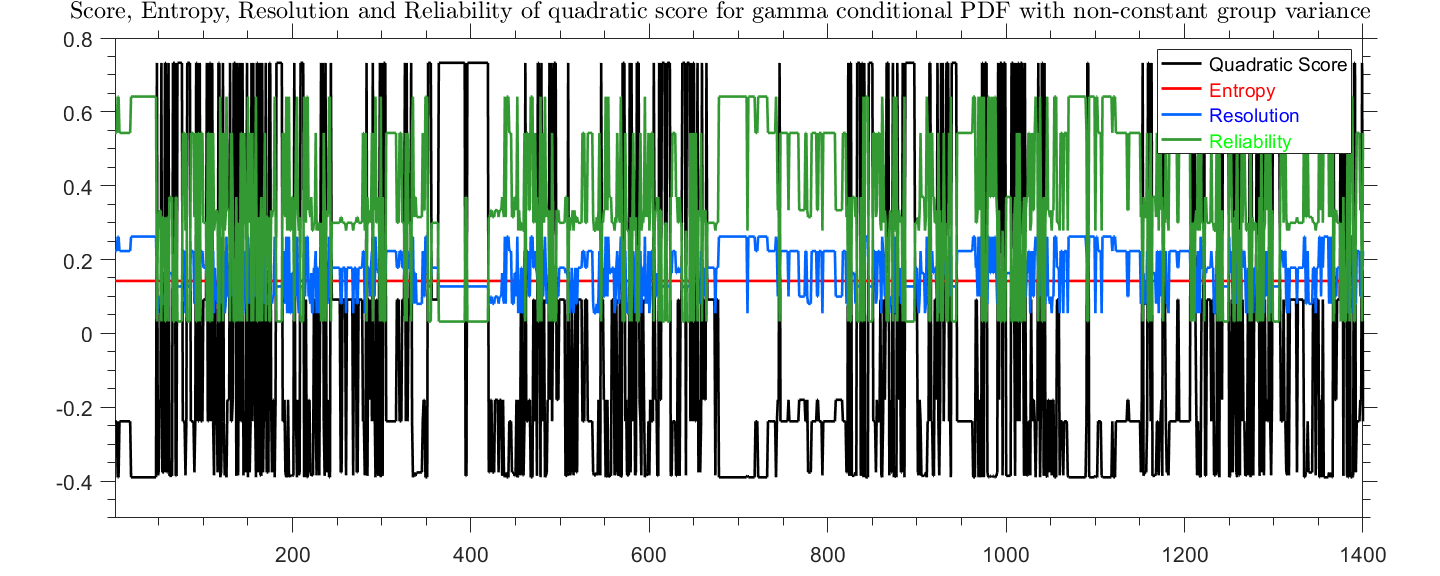

zz = 9; % Plot gamma distribution with group heteroscedastic variance
blue_color = [0 102 255]/255; red_color = [255 0 0]/255; green_color = [51 153 51]/255;
fontsize_ax = 16;
% Figure window
figure('unit','inches','PaperOrientation','portrait','position',[0.1 0.6 15 6]);
% Time window
t_id = 1:1400; nt = numel(t_id); y_min = -0.5; y_max = 0.8;
ax1 = axes('units','inches'); axpos = [ 1.2 , 0.6 , 13 , 5 ]; set(ax1,'position',axpos);
plot(ax1,t_id,S(t_id,zz),'color','k','linewidth',2); hold on
plot(ax1,t_id,E(t_id,zz),'color',red_color,'linewidth',2);
plot(ax1,t_id,Res(t_id,zz),'color',blue_color,'linewidth',2);
plot(ax1,t_id,Rel(t_id,zz),'color',green_color,'linewidth',2);
legend({'\color{black} Quadratic Score','\color{red_color} Entropy', ...
    '\color{blue_color} Resolution','\color{green_color} Reliability'});
% Adjust figure settings
set(ax1,'tickdir','out','XMinorTick','on','YMinorTick','on',...
    'TickLength',[0.012 0.024],'box','off');
set(ax1,'fontsize',fontsize_ax,'box','on');
% Add title
text(-50,0.87,['Score, Entropy, Resolution and Reliability of quadratic score' ...
    ' for gamma conditional PDF with non-constant group variance'],'fontsize',18)
% Adjust axis
axis([t_id(1) t_id(end) y_min y_max]);